**Exercise 1: Least Squares**

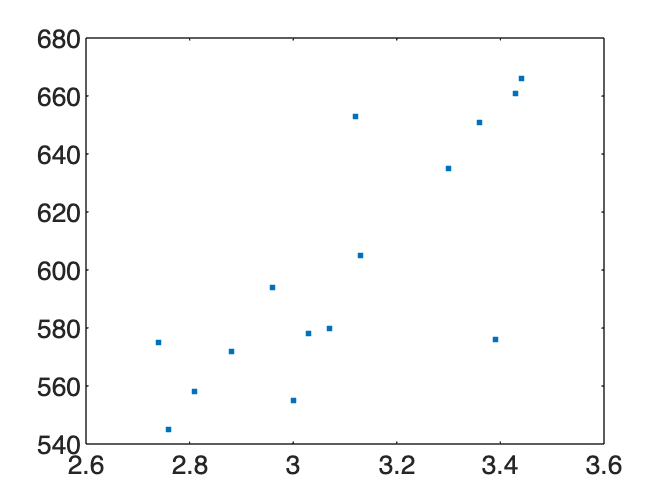

load lawdata.mat
plot(gpa, lsat, ".")


% linear
y = lsat

y =    576
   635
   558
   578
   666
   580
   555
   661
   651
   605


sz = size(gpa)

sz =     15     1


a1 = ones(sz(1), 1)

a1 =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


a2 = gpa

a2 =                       3.39
                       3.3
                      2.81
                      3.03
                      3.44
                      3.07
                         3
                      3.43
                      3.36
                      3.13


A_l = horzcat(a1, a2)

A_l =                          1                      3.39
                         1                       3.3
                         1                      2.81
                         1                      3.03
                         1                      3.44
                         1                      3.07
                         1                         3
                         1                      3.43
                         1                      3.36
                         1                      3.13



Astar = A_l'*A_l

Astar =                         15                     46.42
                     46.42                  144.4846


ystar = A_l'*y

ystar =         9004
       27975


c_l = Astar\ystar

c_l =           187.899587234787
           133.25088736489



% quadratic
y = lsat

y =    576
   635
   558
   578
   666
   580
   555
   661
   651
   605


sz = size(gpa)

sz =     15     1


a1 = ones(sz(1), 1)

a1 =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


a2 = gpa

a2 =                       3.39
                       3.3
                      2.81
                      3.03
                      3.44
                      3.07
                         3
                      3.43
                      3.36
                      3.13


a3 = gpa .^ 2

a3 =                    11.4921
                     10.89
                    7.8961
                    9.1809
                   11.8336
                    9.4249
                         9
                   11.7649
                   11.2896
                    9.7969


A_q = horzcat(a1, a2, a3)

A_q =                          1                      3.39                   11.4921
                         1                       3.3                     10.89
                         1                      2.81                    7.8961
                         1                      3.03                    9.1809
                         1                      3.44                   11.8336
                         1                      3.07                    9.4249
                         1                         3                         9
                         1                      3.43                   11.7649
                         1                      3.36                   11.2896
                         1                      3.13                    9.7969



Astar = A_q'*A_q

Astar =                         15                     46.42                  144.4846
                     46.42                  144.4846                 452.28331
                  144.4846                 452.28331             1423.72093798


ystar = A_q'*y

ystar =                       9004
                     27975
                87416.8686


c_q = Astar\ystar

c_q =           517.282626787634
         -80.2953091303147
          34.4124484409736



% cubic
y = lsat

y =    576
   635
   558
   578
   666
   580
   555
   661
   651
   605


sz = size(gpa)

sz =     15     1


a1 = ones(sz(1), 1)

a1 =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


a2 = gpa

a2 =                       3.39
                       3.3
                      2.81
                      3.03
                      3.44
                      3.07
                         3
                      3.43
                      3.36
                      3.13


a3 = gpa .^ 2

a3 =                    11.4921
                     10.89
                    7.8961
                    9.1809
                   11.8336
                    9.4249
                         9
                   11.7649
                   11.2896
                    9.7969


a4 = gpa .^ 3

a4 =                  38.958219
                    35.937
                 22.188041
                 27.818127
                 40.707584
                 28.934443
                        27
                 40.353607
                 37.933056
                 30.664297


A_c = horzcat(a1, a2, a3, a4)

A_c =                          1                      3.39                   11.4921                 38.958219
                         1                       3.3                     10.89                    35.937
                         1                      2.81                    7.8961                 22.188041
                         1                      3.03                    9.1809                 27.818127
                         1                      3.44                   11.8336                 40.707584
                         1                      3.07                    9.4249                 28.934443
                         1                         3                         9                        27
                         1                      3.43                   11.7649                 40.353607
                         1                      3.36                   11.2896                 37.933056
                         1                      3


Astar = A_c'*A_c

Astar =                         15                     46.42                  144.4846                 452.28331
                     46.42                  144.4846                 452.28331             1423.72093798
                  144.4846                 452.28331             1423.72093798           4506.1046679262
                 452.28331             1423.72093798           4506.1046679262          14337.1363555605


ystar = A_c'*y

ystar =                       9004
                     27975
                87416.8686
             274705.967952


c_c = Astar\ystar

c_c =            12987.751480115
         -12296.0363947091
          4009.85686633919
         -429.803231407328



% plot
linear = c_l(1) + gpa .* c_l(2)

linear =           639.620095401764
          627.627515538924
          562.334580730128
          591.649775950404
          646.282639770009
          596.979811444999
          587.652249329457
           644.95013089636
          635.622568780817
          604.974864686893


quadratic = c_q(1) + gpa .* c_q(2) + (gpa .^2) .* c_q(3)

quadratic =            640.55282756438
          627.059670179798
          563.376942266222
          589.925088014515
          648.289913250457
            595.1099130689
          586.108735365453
          646.728731133865
          635.993166028993
          603.093625341124


cubic = c_c(1) + c_c(2) .* gpa + c_c(3) .* (gpa.^2) + c_c(4) .* (gpa.^3)

cubic =           641.495779633569
          632.333924923778
          561.628292885163
          588.535232020617
          644.177349842077
          595.302627547311
          583.666845042701
          643.801005515539
          638.999226160387
          605.710359080056


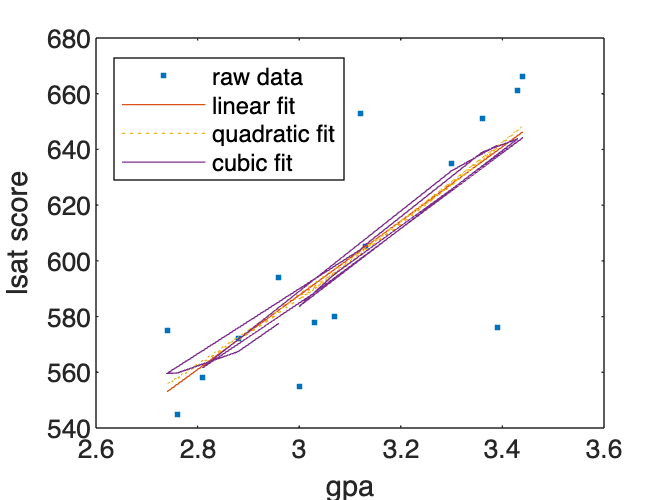


figure
plot(gpa, lsat, ".")
hold on
plot(gpa, linear)
plot(gpa, quadratic, ":")
plot(gpa, cubic) % idk why it's plotting weirdly
hold off
legend("raw data", "linear fit", "quadratic fit", "cubic fit", "Location", "northwest")
xlabel("gpa")
ylabel("lsat score")


% error thing
yl = A_l * c_l

yl =           639.620095401764
          627.627515538924
          562.334580730128
          591.649775950404
          646.282639770009
          596.979811444999
          587.652249329457
           644.95013089636
          635.622568780817
          604.974864686893


yq = A_q * c_q

yq =            640.55282756438
          627.059670179798
          563.376942266222
          589.925088014515
          648.289913250457
            595.1099130689
          586.108735365453
          646.728731133865
          635.993166028993
          603.093625341124


yc = A_c * c_c

yc =           641.495779633576
          632.333924923777
          561.628292885168
          588.535232020617
          644.177349842076
          595.302627547313
          583.666845042711
          643.801005515539
          638.999226160392
          605.710359080055



mse = cumsum(yl.^2)

mse =           409113.866441762
          803030.164703324
          1119250.34538825
          1469299.80277042
          1886981.05323851
          2243365.94851141
          2588701.11465338
          3004661.78599662
          3408677.83594014
          3774672.42284306


mse = mse/length(yl)

mse =           27274.2577627841
          53535.3443135549
          74616.6896925502
          97953.3201846944
          125798.736882567
          149557.729900761
          172580.074310226
          200310.785733108
          227245.189062676
          251644.828189538


mseL = mse(end)

mseL =           361302.763832988


mse = cumsum(yq.^2)

mse =           410307.924900723
           803511.75486672
          1120905.33394396
          1468916.94341289
          1889196.75503518
          2243352.56366805
          2586876.01333974
          3005134.06501376
          3409621.37224934
          3773343.29317644


mse = mse/length(yq)

mse =           27353.8616600482
           53567.450324448
          74727.0222629305
          97927.7962275261
          125946.450335678
           149556.83757787
          172458.400889316
          200342.271000917
          227308.091483289
          251556.219545096


mseQ = mse(end)

mseQ =           361305.332149611


mse = cumsum(yc.^2)

mse =            411516.83528769
          811363.027897198
          1126789.36726631
          1473163.08659587
          1888127.54464543
          2242512.76301016
          2583179.74901228
          2997659.48371509
          3405979.49474867
          3772864.53384556


mseC = mse(end)/length(yc)

mseC =           361314.284126784



format longG
mseL

mseL =           361302.763832988


mseQ

mseQ =           361305.332149611


mseC

mseC =           361314.284126784



% idk why this one is so weird but part marks
% for the win ig
